## Plot data and external control signal

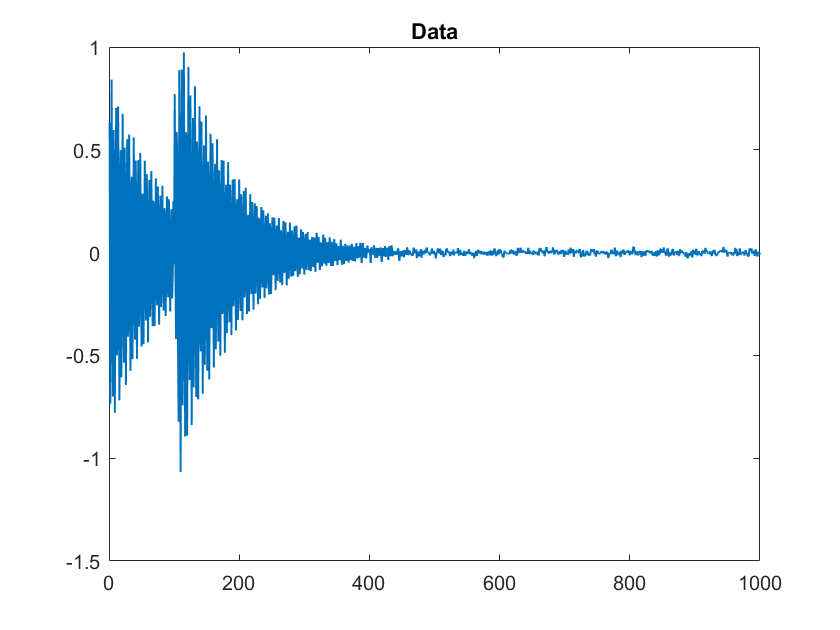

clear all;
% Build example dynamics matrix
seed = 17;
n = 2;                  % Matrix size; should be even
m = 1000;               % Number of data points
eigenvalue_min = 0.95;  % Minimum eigenvalue; 1.0 = stable
[X_dmd, A] = test_dmd_dat(n, m, 0, eigenvalue_min, seed);

% Build random controller
ctr_timing = 100:105;
U = zeros(1,m-1);
U(ctr_timing) = 1.0;

% Generate controlled data
x0 = X_dmd(:,1);
B = ones(n,1);
X_true = real(calc_reconstruction_dmd(x0, [], A, B, U));
% Add noise
noise = 0.01;
X = X_true + noise*randn(size(X_true));

% Plot
figure('DefaultAxesFontSize', 24);
plot(1:m,X(1,:), 'LineWidth', 1)
title("Data")

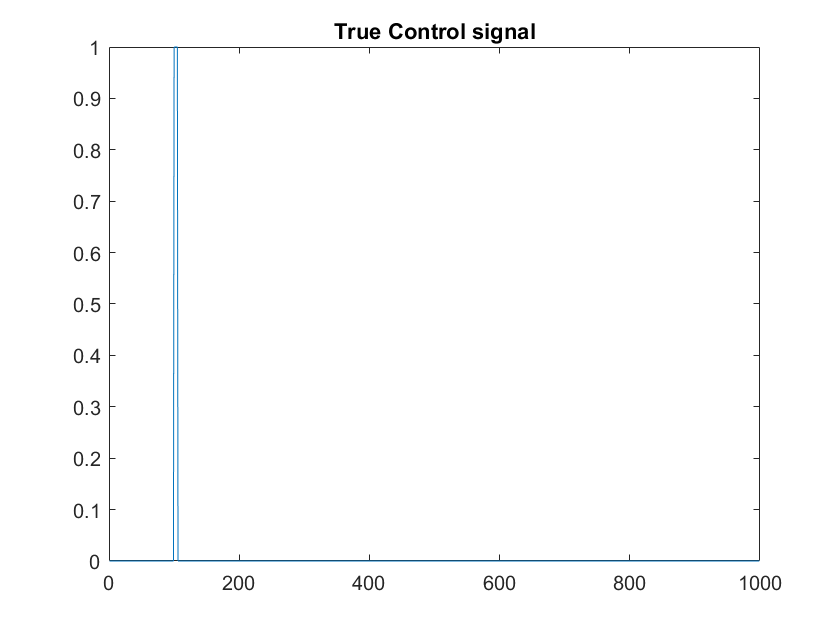


figure;
plot(1:m-1,U)
title("True Control signal")

## Get path of control signals

% Returns a data class with control signals of increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals to search for
                  'verbose',false, ... 
                   'num_iter',100); % Number of iterations
control_signal_path = learn_control_signals(X, settings);

All control signals are 0. Stopping early (this is nothing to worry about)


## Cross-validation

% Get the CV error with uncertainty
max_iter = settings.num_iter;
k = 5;
num_error_steps = 10;

all_err = zeros(max_iter, k-1);
all_err_means = zeros(max_iter, 1);
for i = 1:max_iter
    this_U = control_signal_path.all_U{i};
    [all_err_means(i), all_err(i,:)] = dmdc_cross_val(X, this_U, k, num_error_steps);
end

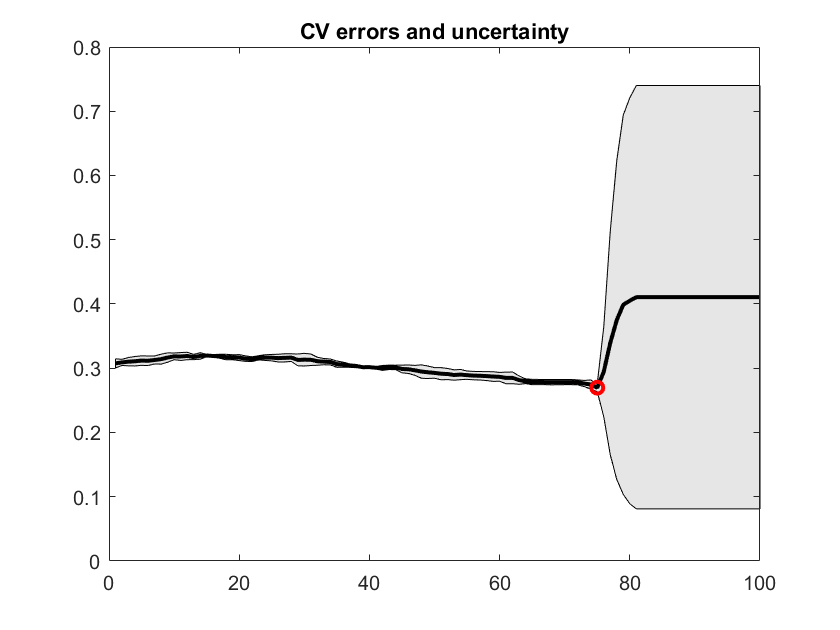


all_err_std = std(all_err, [], 2);

% Get 1 se above the minimum
min_1se_ind = min_1se(all_err_means, all_err_std);

% Plot CV errors
plot_std_fill(all_err, 2);
title("CV errors and uncertainty")
hold on;
plot(min_1se_ind, all_err_means(min_1se_ind), 'ro', 'LineWidth',2)

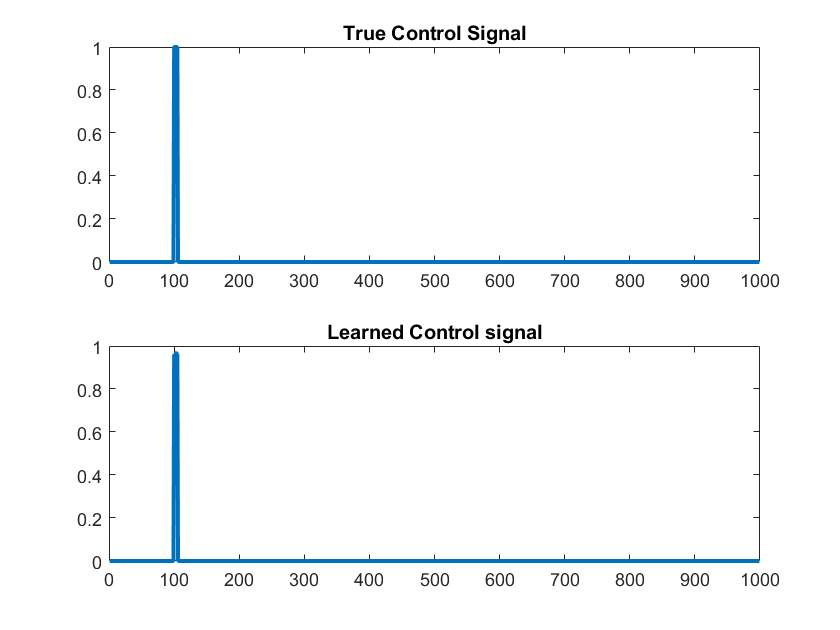

% Use the min+1se as the best control signal
best_U = control_signal_path.all_U{min_1se_ind};
% best_U = control_signal_path.all_U{min_1se_ind+10};

% Plot
figure('DefaultAxesFontSize', 24);
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U, 'linewidth', 2)
title("Learned Control signal")

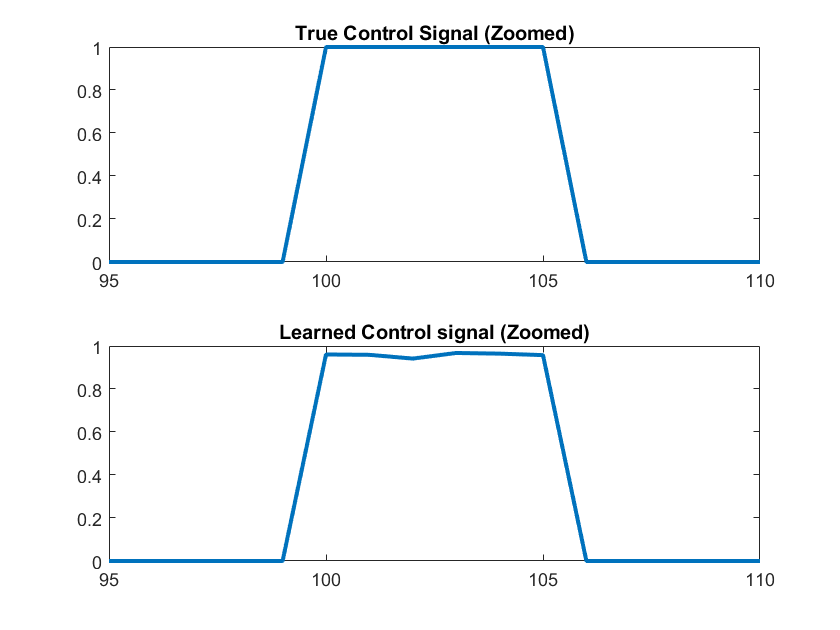


figure('DefaultAxesFontSize', 24);
ind = 95:110;
subplot(2,1,1)
plot(ind, U(ind), 'linewidth', 2)
title("True Control Signal (Zoomed)")
subplot(2,1,2)
plot(ind, best_U(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed)")